# 利用extendedObjectMesh制作一辆液罐车外观

戚笑景 2023210322  清华大学 车辆与运载学院

## 1 基本操作

我们需要利用extendedObjectMesh来实现这个功能，可以先看一下我们的目标类似什么样子

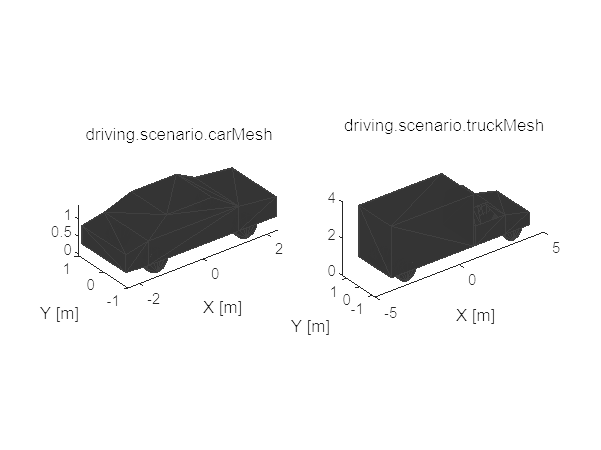

figure
subplot(1,2,1)
show_mesh(driving.scenario.carMesh,'driving.scenario.carMesh');
subplot(1,2,2)
show_mesh(driving.scenario.truckMesh,'driving.scenario.truckMesh');

我们可以看到，车辆中心在[0,0]点，且车辆轮胎底部接触地面的位置就是高度为0的平面，车头朝向X轴正方向。

接下来就是看一下我们有哪些基本图形，以及如何变形

### （1） translate(mesh,[x y z]) 平移网格

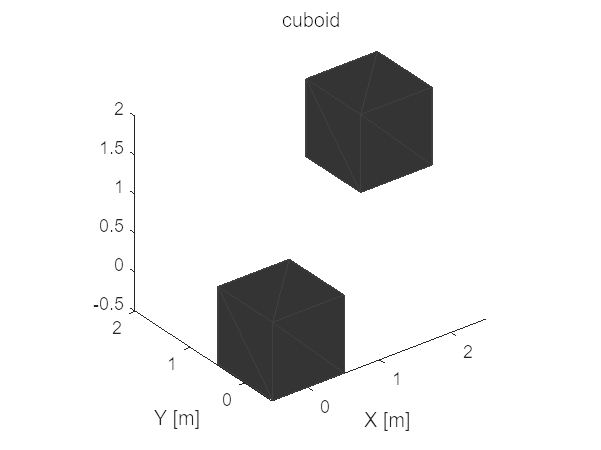

mesh_name = 'cuboid'; % 立方体
mesh_cuboid = extendedObjectMesh(mesh_name);
figure
show_mesh(mesh_cuboid,mesh_name)
hold on
show_mesh(translate(mesh_cuboid,[2,1,1.5]),mesh_name) % translate平移

### （2）rotate(mesh,[xdeg,ydeg,zdeg])绕着绝对的x y z轴旋转网格

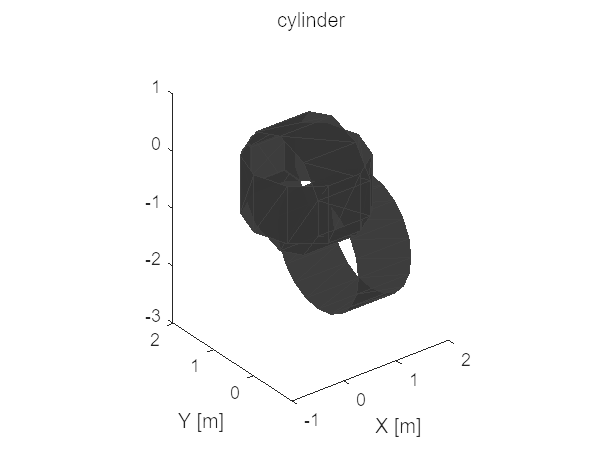

mesh_name = 'cylinder'; % 圆柱体
mesh_cylinder = extendedObjectMesh(mesh_name);
mesh_cylinder_n = extendedObjectMesh(mesh_name,20); % 指定侧面划分的面数
figure
show_mesh(mesh_cylinder,mesh_name)
hold on
show_mesh(rotate(mesh_cylinder,[0 90 0]),mesh_name) % rotate旋转指定度数
show_mesh(rotate(translate(mesh_cylinder_n,[2,1,1.5]),[0 90 0]),mesh_name) % rotate旋转指定度数

### （3）scale(mesh,[x y z])以绝对x y z平面缩放网格

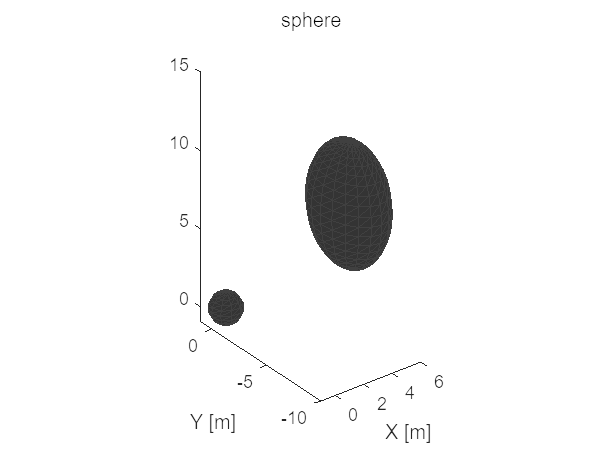

mesh_name = 'sphere'; % 球体
mesh_sphere = extendedObjectMesh(mesh_name);
mesh_sphere_n = extendedObjectMesh(mesh_name,20);
figure
show_mesh(mesh_sphere,mesh_name)
hold on
show_mesh(scale(translate(mesh_sphere_n,[2,-2,2]),[2 3 4]),mesh_name) % scale缩放指定倍数

### （4）applyTransform(mesh,T)自定义一系列转换并作用于网格

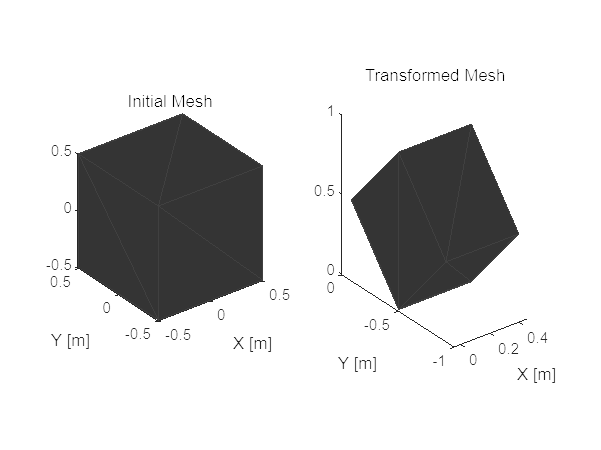

cuboid = extendedObjectMesh('cuboid');
tform = makehgtform('translate',[0.2 -0.5 0.5], ...
    'scale',[0.5 0.6 0.7], ...
    'xrotate',pi/4);
transformedCuboid = applyTransform(cuboid,tform);
figure
subplot(1,2,1);
show_mesh(cuboid,'Initial Mesh')

subplot(1,2,2);
show_mesh(transformedCuboid,'Transformed Mesh')

### （5）join(mesh1,mesh2)合并2个mesh

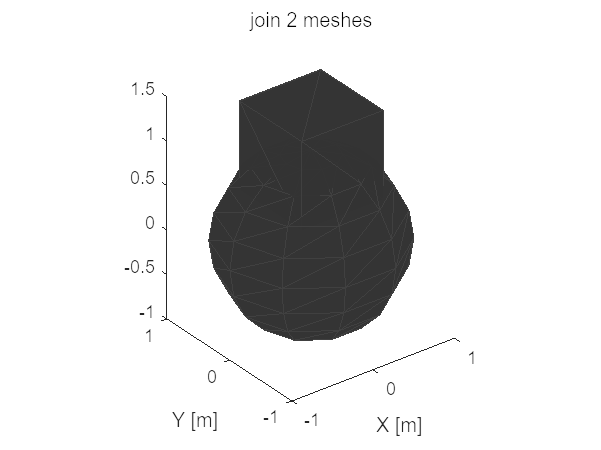

sph = extendedObjectMesh('sphere');
cub = extendedObjectMesh('cuboid');
cub = translate(cub,[0 0 1]);
sphCub = join(sph,cub);
figure,show_mesh(sphCub,'join 2 meshes');

### （6）scaleToFit(mesh,dims)按照指定的维度进行缩放

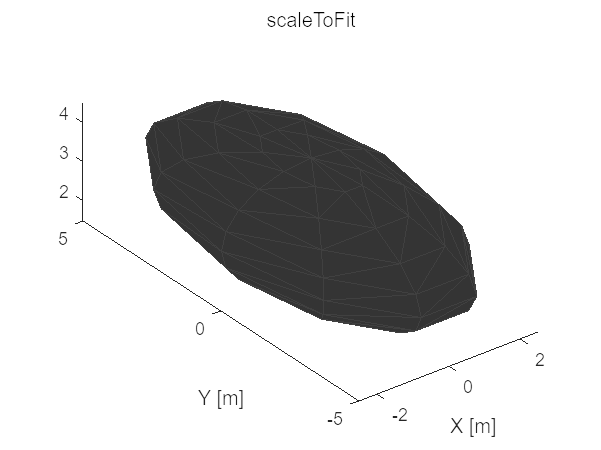

sph = extendedObjectMesh('sphere');
dims = struct('Length',5,'Width',10,'Height',3,'OriginOffset',[0 0 -3]);
sph = scaleToFit(sph,dims);
figure,show_mesh(sph,'scaleToFit');

### （7）自己设计车头

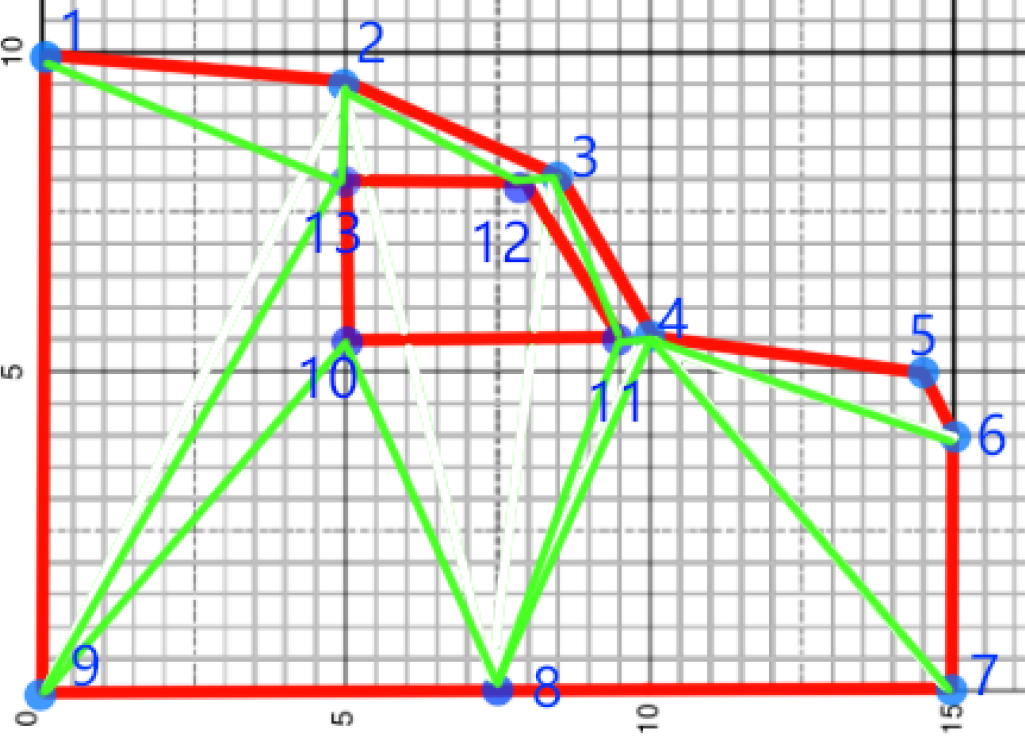

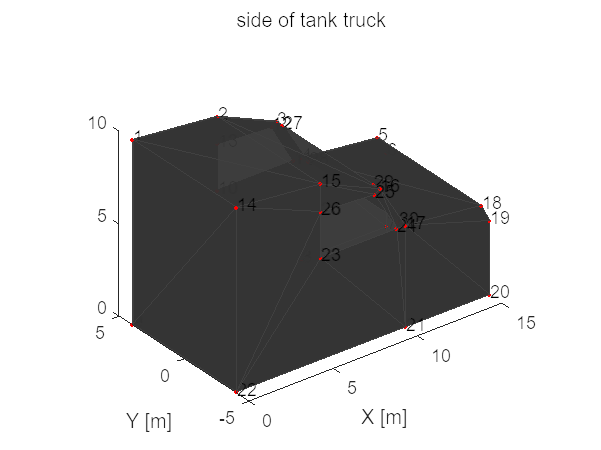

vertices = [0 0 10;
           5  0 9.5;
           8.5 0  8;
           10  0 5.5;
           14.5 0 5;
           15  0 4;
           15  0 0;
           10  0 0;
           0 0 0;
           5 0 5.5;
           9.5 0  5.5;
           8.2 0 7.8;
           5  0 8];
np_1 = size(vertices,1);
faces = [1 13 9;
         1 2 13;
         9 13 10;
         9 10 8;
         2 13 12;
         2 3 12;
         12 3 11;
         8 10 11;
         4 8 11;
         3 4 11;
         4 5 6;
         4 6 7;
         4 7 8];
vertices = [vertices(:,1),4*ones(np_1,1),vertices(:,3);
            vertices(:,1),-4*ones(np_1,1),vertices(:,3);
           8.5 3.5  8;
           10  3.5 5.5;
           8.5 -3.5  8;
           10  -3.5 5.5;];
faces = [faces;faces+np_1;
    1 14 9;
    9 14 22;
    1 2 15;
    1 14 15;
    2 15 16;
    16 2 3;
    18 5 6;
    18 6 19;
    19 6 20;
    6 7 20;
    7 21 8;
    7 20 21;
    22 21 9;
    9 8 21;
    16 17 29;
    29 30 17;
    3 4 27;
    27 28 4;
    4 17 18;
    4 5 18];
side_mesh = extendedObjectMesh(vertices,faces);
figure,show_mesh(side_mesh,'side of tank truck')
hold on,show_vertices(vertices)

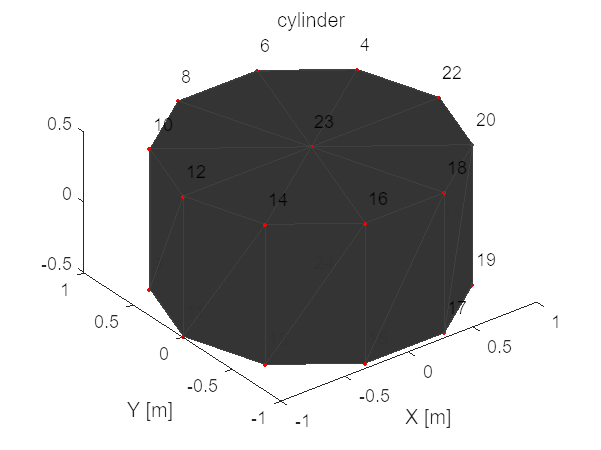

cub = extendedObjectMesh('cuboid');
wheel = extendedObjectMesh('cylinder');
wheel.Vertices = [wheel.Vertices;
                  0 0 0.5;0 0 -0.5];
wheel.Faces = [wheel.Faces;
               24 1 3;
               24 3 5;
               24 5 7;
               24 7 9;
               24 9 11;
               24 11 13;
               24 13 15;
               24 15 17;
               24 17 19;
               24 19 21;
               23 2 4;
               23 4 6;
               23 6 8;
               23 8 10;
               23 10 12;
               23 12 14;
               23 14 16;
               23 16 18;
               23 18 20;
               23 20 22];
figure,show_mesh(wheel,'cylinder')
hold on,show_vertices(wheel.Vertices)

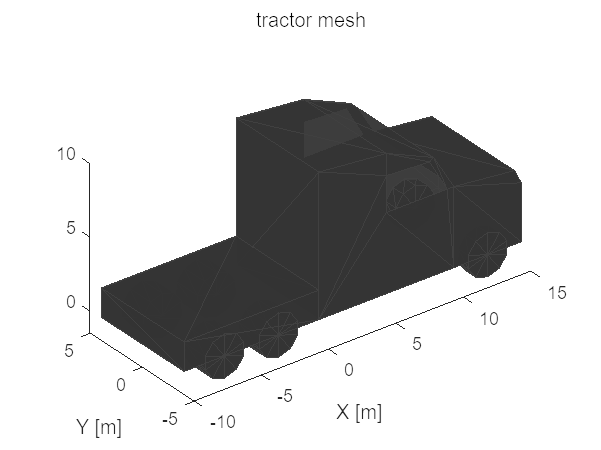



wheel = rotate(wheel,[0,90,90]);
wheel_front = scale(wheel,[1.5 1 1.5]);
wheel_double = scale(wheel,[1.5 2 1.5]);

tractor_plate = scale(cub,[10 8 2]);
tractor_plate = translate(tractor_plate,[-5,0,1]);
tractor_mesh = join(tractor_plate,side_mesh);

wheel_front_L = translate(wheel_front,[12.5 3.5 0]);
wheel_front_R = translate(wheel_front,[12.5 -3.5 0]);
tractor_mesh = join(tractor_mesh,wheel_front_L);
tractor_mesh = join(tractor_mesh,wheel_front_R);
wheel_L = translate(wheel_double,[-3 3 0]);
wheel_R = translate(wheel_double,[-3 -3 0]);
tractor_mesh = join(tractor_mesh,wheel_L);
tractor_mesh = join(tractor_mesh,wheel_R);
wheel_L = translate(wheel_double,[-7 3 0]);
wheel_R = translate(wheel_double,[-7 -3 0]);
tractor_mesh = join(tractor_mesh,wheel_L);
tractor_mesh = join(tractor_mesh,wheel_R);
figure,show_mesh(tractor_mesh,'tractor mesh')

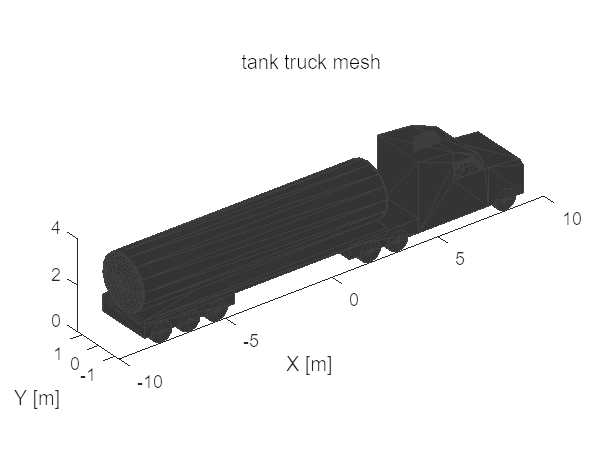


sph = extendedObjectMesh('sphere',15);
sph = rotate(sph,[0 90 0]);
tank_mesh = extendedObjectMesh('cylinder',15);
tank_mesh = rotate(tank_mesh,[0 90 0]);
tank_mesh = scale(tank_mesh,[35 4 4]);
tank_mesh = translate(tank_mesh,[-22 0 6]);

tractor_plate = scale(cub,[35 8 1]);
tractor_plate = translate(tractor_plate,[-22,0,2]);
tank_mesh = join(tank_mesh,tractor_plate);
tractor_plate = scale(cub,[13 8 2]);
tractor_plate = translate(tractor_plate,[-33,0,1]);
tank_mesh = join(tank_mesh,tractor_plate);

wheel_L = translate(wheel_double,[-29 3 0]);
wheel_R = translate(wheel_double,[-29 -3 0]);
tank_mesh = join(tank_mesh,wheel_L);
tank_mesh = join(tank_mesh,wheel_R);

wheel_L = translate(wheel_double,[-33 3 0]);
wheel_R = translate(wheel_double,[-33 -3 0]);
tank_mesh = join(tank_mesh,wheel_L);
tank_mesh = join(tank_mesh,wheel_R);

wheel_L = translate(wheel_double,[-37 3 0]);
wheel_R = translate(wheel_double,[-37 -3 0]);
tank_mesh = join(tank_mesh,wheel_L);
tank_mesh = join(tank_mesh,wheel_R);

wall = scale(sph,[0.5,4,4]);
front_wall = translate(wall,[-39.5 0 6]);
back_wall = translate(wall,[-4.5 0 6]);
tank_mesh = join(tank_mesh,front_wall);
tank_mesh = join(tank_mesh,back_wall);

tankTruckMesh = join(tractor_mesh,tank_mesh);
dims = struct('Length',18,'Width',2.55,'Height',3.5,'OriginOffset',[0 0 -1.75]);
tankTruckMesh = scaleToFit(tankTruckMesh,dims);
figure,show_mesh(tankTruckMesh,'tank truck mesh')


save tankTruckMesh_COMPASS.mat tankTruckMesh


cub = extendedObjectMesh('cuboid');
wheel = extendedObjectMesh('cylinder');
wheel.Vertices = [wheel.Vertices;
                  0 0 0.5;0 0 -0.5];
wheel.Faces = [wheel.Faces;
               24 1 3;
               24 3 5;
               24 5 7;
               24 7 9;
               24 9 11;
               24 11 13;
               24 13 15;
               24 15 17;
               24 17 19;
               24 19 21;
               23 2 4;
               23 4 6;
               23 6 8;
               23 8 10;
               23 10 12;
               23 12 14;
               23 14 16;
               23 16 18;
               23 18 20;
               23 20 22];
figure,show_mesh(wheel,'cylinder')
hold on,show_vertices(wheel.Vertices)



wheel = rotate(wheel,[0,90,90]);
wheel_front = scale(wheel,[1.5 1 1.5]);
wheel_double = scale(wheel,[1.5 2 1.5]);

tractor_plate = scale(cub,[10 8 2]);
tractor_plate = translate(tractor_plate,[-5,0,1]);
tractor_mesh = join(tractor_plate,side_mesh);

wheel_front_L = translate(wheel_front,[12.5 3.5 0]);
wheel_front_R = translate(wheel_front,[12.5 -3.5 0]);
tractor_mesh = join(tractor_mesh,wheel_front_L);
tractor_mesh = join(tractor_mesh,wheel_front_R);
wheel_L = translate(wheel_double,[-3 3 0]);
wheel_R = translate(wheel_double,[-3 -3 0]);
tractor_mesh = join(tractor_mesh,wheel_L);
tractor_mesh = join(tractor_mesh,wheel_R);
wheel_L = translate(wheel_double,[-7 3 0]);
wheel_R = translate(wheel_double,[-7 -3 0]);
tractor_mesh = join(tractor_mesh,wheel_L);
tractor_mesh = join(tractor_mesh,wheel_R);
figure,show_mesh(tractor_mesh,'tractor mesh')

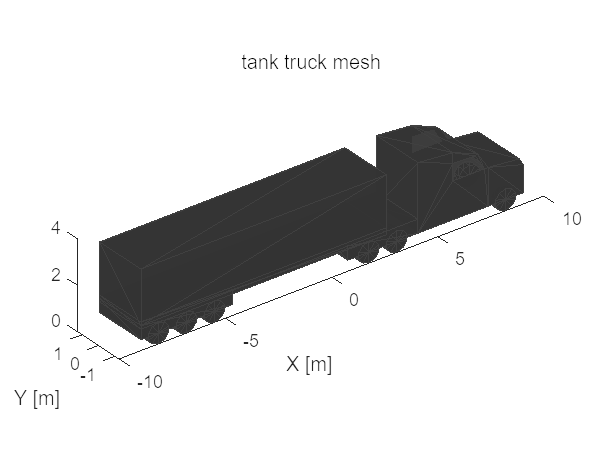


sph = extendedObjectMesh('sphere',15);
sph = rotate(sph,[0 90 0]);
tank_mesh = extendedObjectMesh('cuboid');
tank_mesh = rotate(tank_mesh,[0 90 0]);
tank_mesh = scale(tank_mesh,[35 8 8]);
tank_mesh = translate(tank_mesh,[-22 0 6]);

tractor_plate = scale(cub,[35 8 1]);
tractor_plate = translate(tractor_plate,[-22,0,2]);
tank_mesh = join(tank_mesh,tractor_plate);
tractor_plate = scale(cub,[13 8 2]);
tractor_plate = translate(tractor_plate,[-33,0,1]);
tank_mesh = join(tank_mesh,tractor_plate);

wheel_L = translate(wheel_double,[-29 3 0]);
wheel_R = translate(wheel_double,[-29 -3 0]);
tank_mesh = join(tank_mesh,wheel_L);
tank_mesh = join(tank_mesh,wheel_R);

wheel_L = translate(wheel_double,[-33 3 0]);
wheel_R = translate(wheel_double,[-33 -3 0]);
tank_mesh = join(tank_mesh,wheel_L);
tank_mesh = join(tank_mesh,wheel_R);

wheel_L = translate(wheel_double,[-37 3 0]);
wheel_R = translate(wheel_double,[-37 -3 0]);
tank_mesh = join(tank_mesh,wheel_L);
tank_mesh = join(tank_mesh,wheel_R);


trailerMesh = join(tractor_mesh,tank_mesh);
dims = struct('Length',18,'Width',2.55,'Height',3.5,'OriginOffset',[0 0 -1.75]);
trailerMesh = scaleToFit(trailerMesh,dims);
figure,show_mesh(trailerMesh,'tank truck mesh')


save trailerMesh_COMPASS.mat trailerMesh

function show_mesh(mesh,title_string)
    if nargin < 2
        title_string = "";
    end
    show(mesh);
    title(title_string)
    xlabel('X [m]')
    ylabel('Y [m]')
end

function show_vertices(vertices)
    scatter3(vertices(:,1),vertices(:,2),vertices(:,3),'r.')
    hold on
    for i = 1:size(vertices,1)
        text(vertices(i,1)+0.1,vertices(i,2)+0.1,vertices(i,3)+0.1,num2str(i));
    end
end